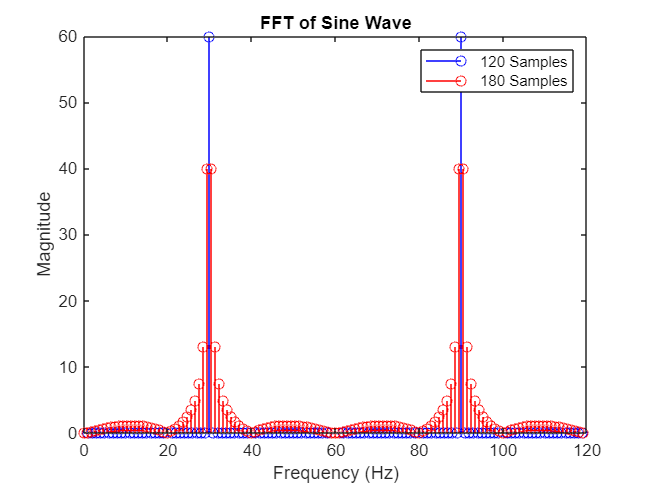

%prob_1 
t = 0 : (2/120) : 2 - (2/120);
x = sin(2*pi*15*t);
y1 = fft(x,120);
m1= abs(y1);
f1=  (0:length(y1)-1);
stem(f1,m1,'b')
hold on 
y2 = fft(x,135);
m2= abs(y2);
f2 =  (0:length(y2)-1)*120/length(y2);
stem(f2,m2,'r')
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT of Sine Wave')
legend('120 Samples', '135 Samples')
hold off

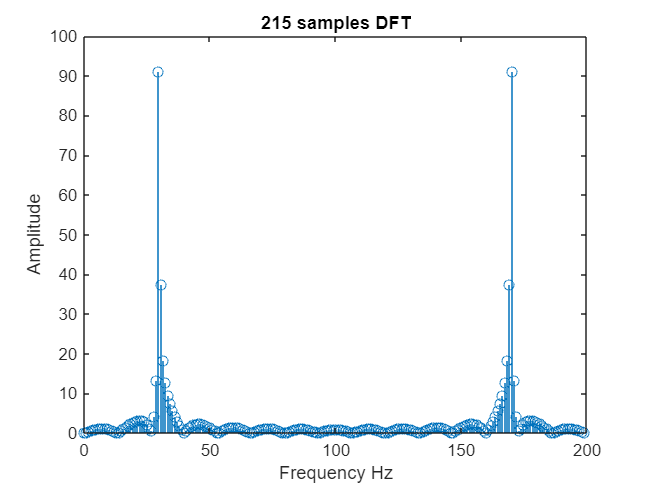

% prob2
clear all;
A=120;B=126;
t=0:10/200: 10-(10/200);
x= 0.1*sin(A*pi*t)+ cos(B*pi*t);
y1= fft(x,215);
y2= fft(x,415);
y3= fft(x,1115);
y4= fft(x,1515);
y5= fft(x,1915);
f1= (0:length(y1)-1)*200/length(y1);
f2= (0:length(y2)-1)*200/length(y2);
f3= (0:length(y3)-1)*200/length(y3);
f4= (0:length(y4)-1)*200/length(y4);
f5= (0:length(y5)-1)*200/length(y5);
m1=abs(y1);
m2=abs(y2);
m3=abs(y3);
m4=abs(y4);
m5=abs(y5);
figure;
stem(f1,m1)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("215 samples DFT")

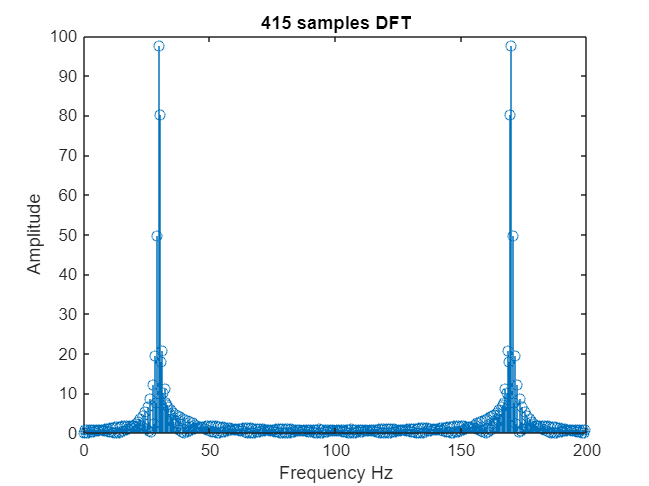

stem(f2,m2)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("415 samples DFT")

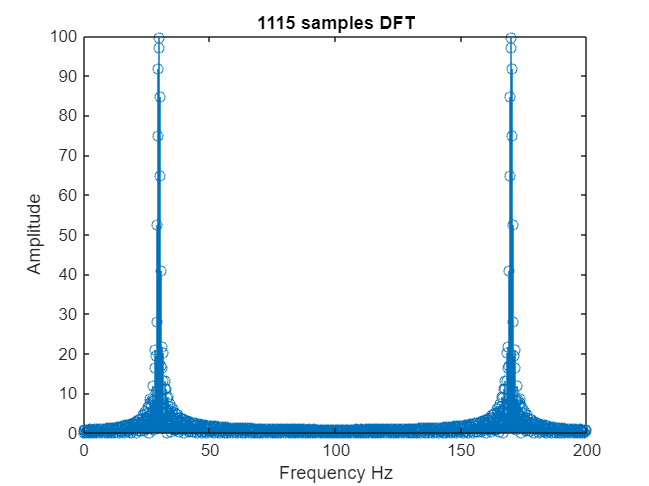

stem(f3,m3)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1115 samples DFT")

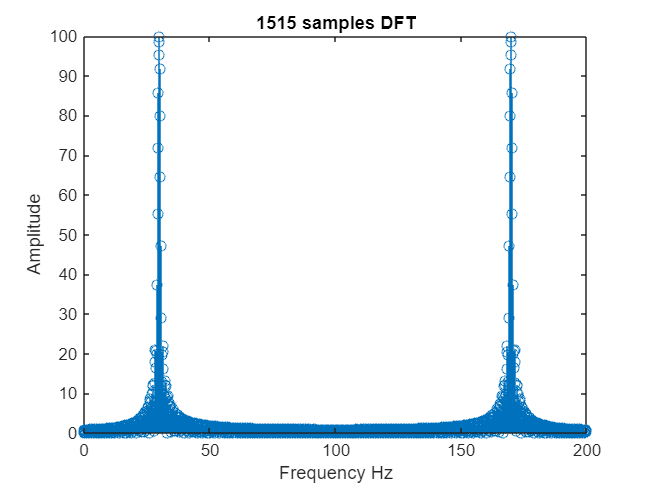

stem(f4,m4)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1515 samples DFT")

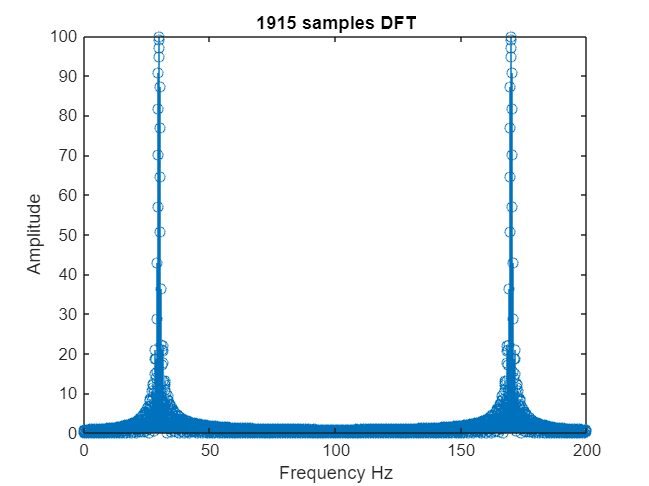

stem(f5,m5)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1915 samples DFT")

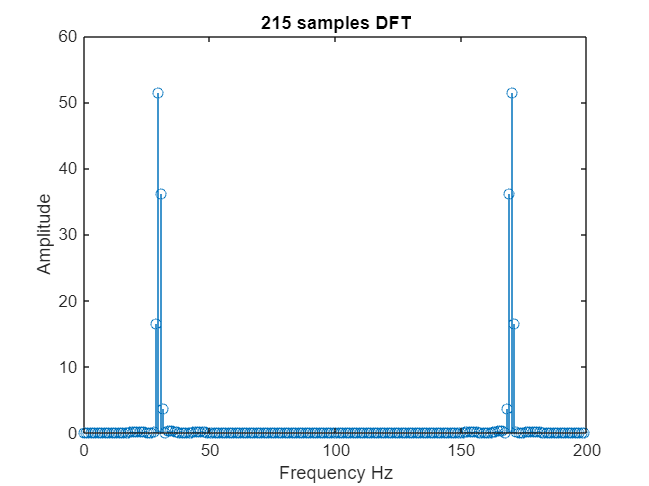

% prob3
clear all;

A=120;B=126;
t=0:10/200: 10-(10/200);
x= 0.1*sin(A*pi*t)+ cos(B*pi*t);
h= hamming (200);
w= x.*h';
y1= fft(w,215);
y2= fft(w,415);
y3= fft(w,1115);
y4= fft(w,1515);
y5= fft(w,1915);
f1= (0:length(y1)-1)*200/length(y1);
f2= (0:length(y2)-1)*200/length(y2);
f3= (0:length(y3)-1)*200/length(y3);
f4= (0:length(y4)-1)*200/length(y4);
f5= (0:length(y5)-1)*200/length(y5);
m1=abs(y1);
m2=abs(y2);
m3=abs(y3);
m4=abs(y4);
m5=abs(y5);
figure;
stem(f1,m1)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("215 samples DFT")

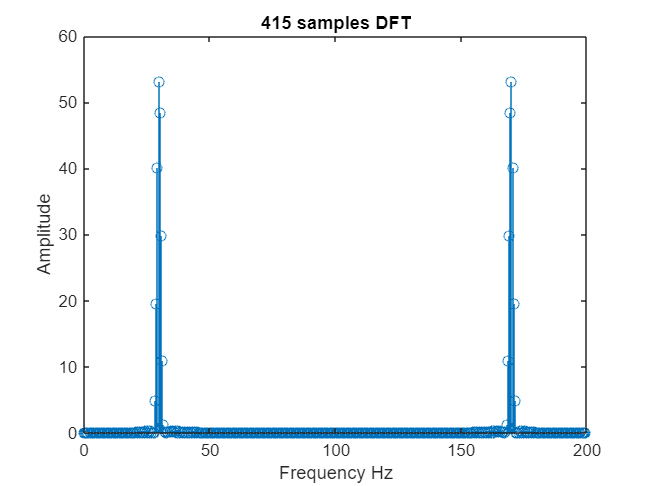

stem(f2,m2)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("415 samples DFT")

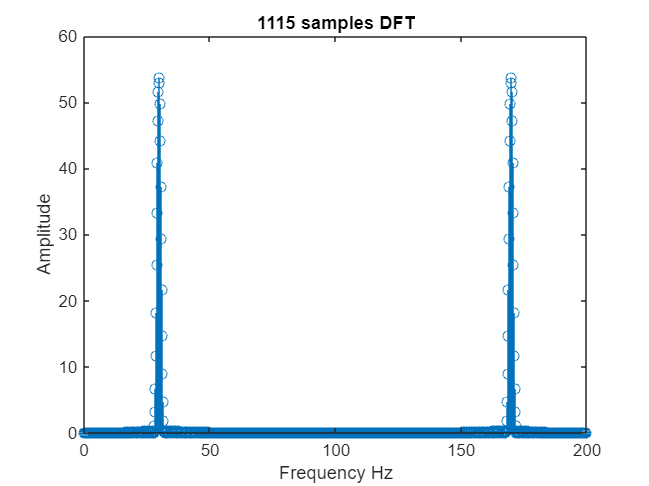

stem(f3,m3)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1115 samples DFT")

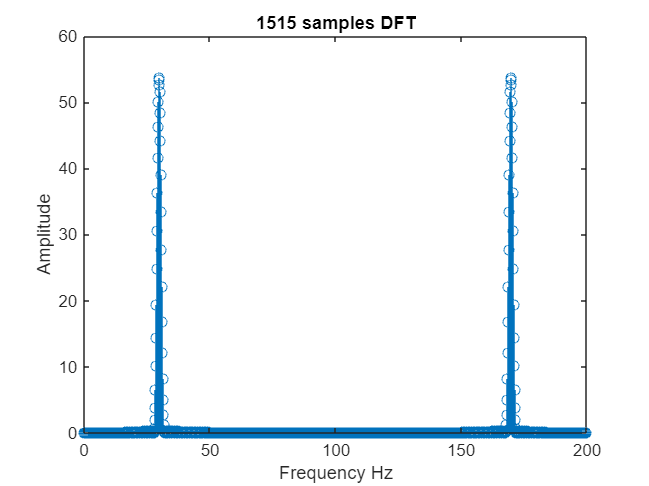

stem(f4,m4)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1515 samples DFT")

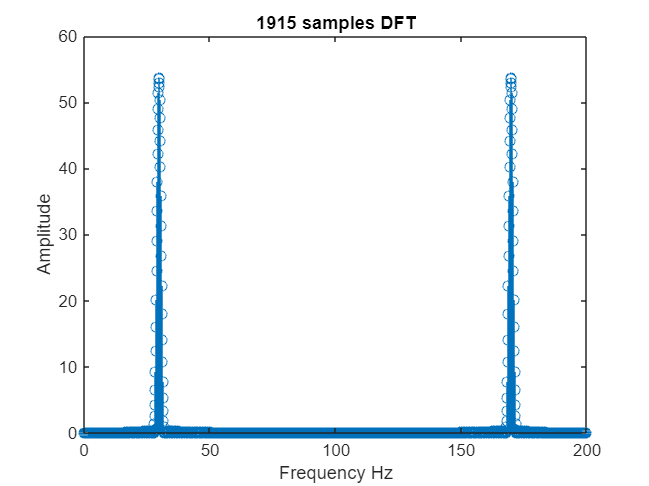

stem(f5,m5)
xlabel("Frequency Hz")
ylabel(" Amplitude ")
title("1915 samples DFT")

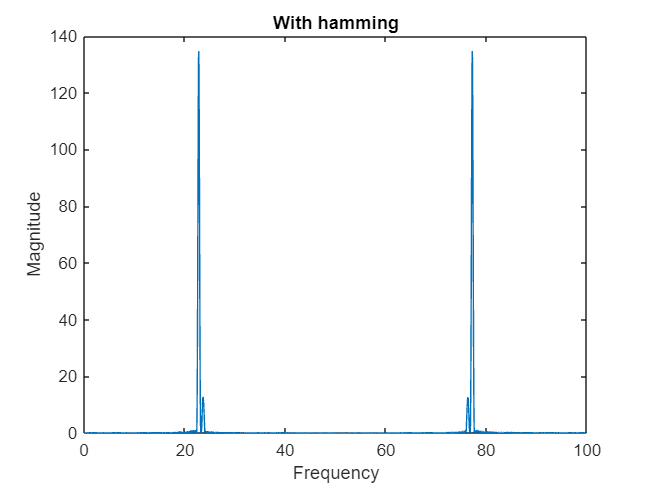

% prob 4
clear all;
% info= load("Exp4Data1.txt");
% ham= hamming(500);
% new= info.*ham';
% figure;
% plot(info)
% plot(new)
%prob 4
x=load("Exp4Data1.txt");
Fs=100;
w = hamming(500);
x1 = x.* w' ;

m1 = abs(fft(x1,10000));
f1 = (0:length(m1)-1)*Fs/length(m1);
figure(2)
plot(f1,m1)
title("With hamming")
xlabel("Frequency");
ylabel("Magnitude");

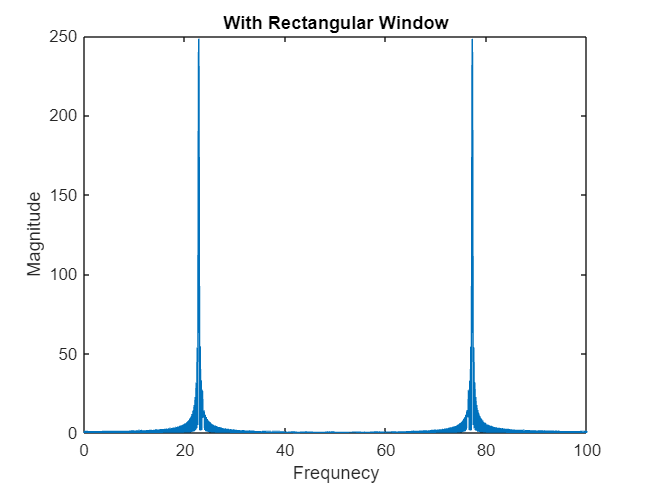

m = abs(fft(x,10000));
f = (0:length(m)-1)*Fs/length(m);
figure(1)
plot(f,m)
title("With Rectangular Window")
xlabel("Frequnecy");
ylabel("Magnitude");

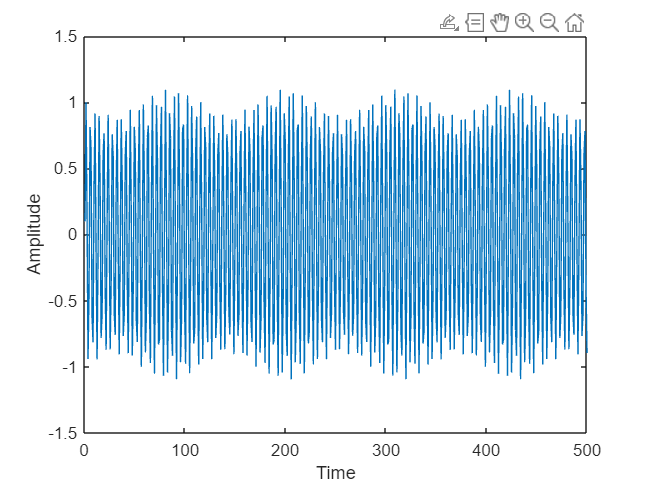

figure(3)
plot(x)
xlabel("Time")
ylabel('Amplitude')

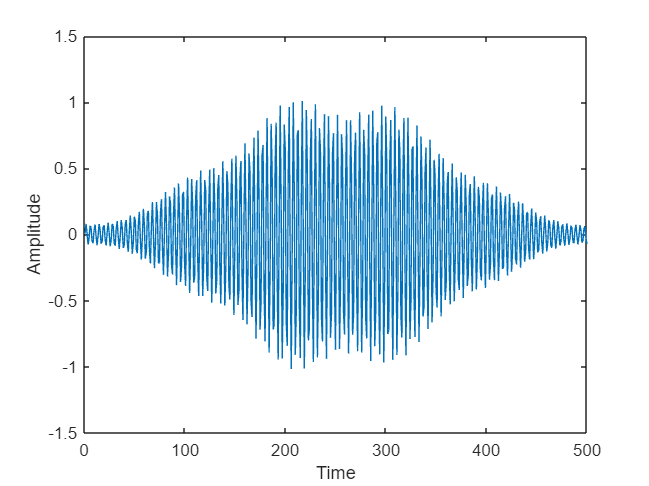

plot(x1)
xlabel("Time")
ylabel('Amplitude')